This script loads epoched EEG data in eeglab data structure, and saves only the data (electrodes x epochs x epochs-timepoints) and event matricies

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\User\eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "Biosig" v3.7.9 to the path - new version 3.8.1 available
EEGLAB: adding "ICLabel" v1.4 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.8 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.0 (see >> help eegplugin_dipfit) - new version 5.2 available
EEGLAB: adding "firfilt" v2.7.1 (see >> help eegplugin_firfilt)


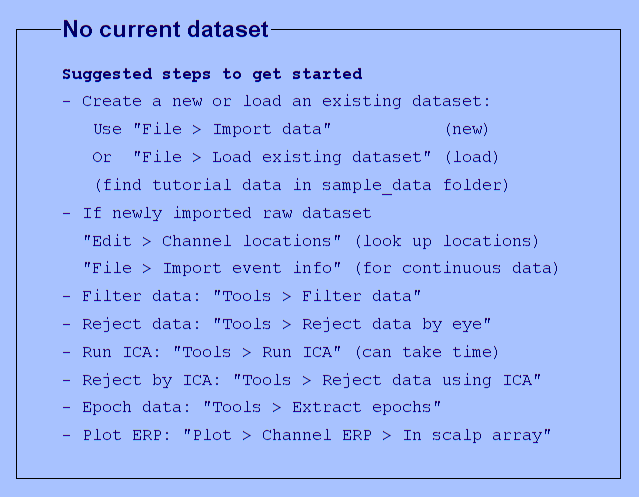

You are using the latest version of EEGLAB.


addpath 'C:\Users\User\Cloud-Drive\BigFiles\libs\eeglab2023.0'
eeglab;

input_dir = 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced';
output_dir = 'C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\';
preproc_name = 'referenced';
import_type = 'allElecd';
sleep_files_name_suffix = strcat('_sleep_',preproc_name,'.set');
wake_night_files_name_suffix = strcat('_wake_night_',preproc_name,'.set');
wake_morning_files_name_suffix = strcat('_wake_morning_',preproc_name,'.set');


electrodes = 1:93;
% electrodes = [5,6,11,80,85]; %% in MNE-python they are [4,5,10,79,84]
% electrodes = [5];

subs = {'08','09','10','11','13','14','15','16','17','19','20','21','23','24','25','26','27','28','29','30','31','32','33','34','35','36','37','38'};

for sub_ind=1:size(subs,2)
    sub_epochs_filename = strcat(output_dir, 'epochs_sub',subs(sub_ind),'_', preproc_name, '_',import_type, '.mat');
    if isfile(sub_epochs_filename)
        string(strcat('Sub_',subs(sub_ind), ' already exists in path:',  sub_epochs_filename))
        continue
    end
    
    isSleepData = 1; isWakeMorningData = 1; isWakeNightData=1;
    %% get sub .set files loaded
    try
        eeglabsub_sleep =  pop_loadset(strcat('s_',subs(sub_ind),sleep_files_name_suffix), input_dir);
        subEvents_sleep = eeglabsub_sleep.event;
        subAllEpochs_sleep = eeglabsub_sleep.data;
        samplefreq = eeglabsub_sleep.srate;
        subAllEpochs_sleep = subAllEpochs_sleep(electrodes,:,:);
    catch ME
        isSleepData = 0;
    end
    
    try
        eeglabsub_wake_night =  pop_loadset( strcat('s_',subs(sub_ind),wake_night_files_name_suffix), input_dir);
        subEvents_wake_night = eeglabsub_wake_night.event;
        subAllEpochs_wake_night = eeglabsub_wake_night.data;
        samplefreq = eeglabsub_sleep.srate;
        subAllEpochs_wake_night = subAllEpochs_wake_night(electrodes,:,:); 
    catch ME
        isWakeNightData = 0;
    end

    try
        eeglabsub_wake_morning =  pop_loadset( strcat('s_',subs(sub_ind),wake_morning_files_name_suffix), input_dir);
        subEvents_wake_morning = eeglabsub_wake_morning.event;
        subAllEpochs_wake_morning = eeglabsub_wake_morning.data;
        samplefreq = eeglabsub_sleep.srate;
        subAllEpochs_wake_morning = subAllEpochs_wake_morning(electrodes,:,:); 
    catch ME
        isWakeMorningData = 0;
    end
    
    
    if isSleepData + isWakeMorningData +isWakeNightData <3
        strcat('Failed to find .set files of Sub',subs(sub_ind))
        isSleepData
        isWakeMorningData
        isWakeNightData
        continue
    end
    
    save(sub_epochs_filename{1}...
    ,"subEvents_sleep","subAllEpochs_sleep","subEvents_wake_night","subAllEpochs_wake_night","subEvents_wake_morning","subAllEpochs_wake_morning","samplefreq");
end

ans = "Sub_08 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub08_referenced_allElecd.mat"

ans = "Sub_09 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub09_referenced_allElecd.mat"

pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_10_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_10_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_10_wake_night_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_10_wake_night_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_10_wake_morning_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_10_wake_morning_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


ans = "Sub_11 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub11_referenced_allElecd.mat"

pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_13_sleep_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_13_sleep_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_13_wake_night_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_13_wake_night_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


pop_loadset(): loading file C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_13_wake_morning_referenced.set ...
Reading float file 'C:\Users\User\OneDrive - huji.ac.il\AnatArzData\Data\rerefrenced\s_13_wake_morning_referenced.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


ans = "Sub_14 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub14_referenced_allElecd.mat"

ans = "Sub_15 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub15_referenced_allElecd.mat"

ans = "Sub_16 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub16_referenced_allElecd.mat"

ans = "Sub_17 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub17_referenced_allElecd.mat"

ans = "Sub_19 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub19_referenced_allElecd.mat"

ans = "Sub_20 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub20_referenced_allElecd.mat"

ans = "Sub_21 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub21_referenced_allElecd.mat"

ans = "Sub_23 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub23_referenced_allElecd.mat"

ans = "Sub_24 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub24_referenced_allElecd.mat"

ans = "Sub_25 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub25_referenced_allElecd.mat"

ans = "Sub_26 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub26_referenced_allElecd.mat"

ans = "Sub_27 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub27_referenced_allElecd.mat"

ans = "Sub_28 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub28_referenced_allElecd.mat"

ans = "Sub_29 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub29_referenced_allElecd.mat"

ans = "Sub_30 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub30_referenced_allElecd.mat"

ans = "Sub_31 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub31_referenced_allElecd.mat"

ans = "Sub_32 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub32_referenced_allElecd.mat"

ans = "Sub_33 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub33_referenced_allElecd.mat"

ans = "Sub_34 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub34_referenced_allElecd.mat"

ans = "Sub_35 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub35_referenced_allElecd.mat"

ans = "Sub_36 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub36_referenced_allElecd.mat"

ans = "Sub_37 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub37_referenced_allElecd.mat"

ans = "Sub_38 already exists in path:C:\Users\User\Cloud-Drive\BigFiles\OmissionExpOutput\timefreq_analysis\import\\matlab_mats\epochs_sub38_referenced_allElecd.mat"

eeglabsub_wake_night =  pop_loadset( strcat('s_32',wake_night_files_name_suffix), input_dir);
subEvents_wake_morning = eeglabsub_wake_night.event;
subAllEpochs_wake_morning = eeglabsub_wake_night.data;

plot(eeglabsub_wake_night.times,subAllEpochs_wake_morning(electrodes(1),:,1675))


c_1 = [42,282,561,641,960,1140,1297,1455,1669,1880,2118,2214,2543,2621,2790,3103,3143,3401,3641,4118,4218,4335,4555];
c_2 = [44,284,563,643,962,1142,1299,1457,1671,1882,2120,2216,2545,2622,2792,3105,3145,3403,3643,3841,4120,4220,4337,4557];
c_3 = [46,285,565,645,964,1144,1301,1459,1673,1884,2122,2218,2547,2624,3107,3147,3405,3645,3843,4122,4222,4339,4559];
c_4 = [48,287,567,647,966,1146,1303,1461,1675,1886,2124,2220,2549,2795,3109,3149,3407,3647,3845,4124,4224,4341,4561];
c_5 = [50,289,569,649,968,1148,1305,1463,1677,1888,2126,2222,2550,2627,2797,3111,3151,3409,3649,3847,4126,4226,4343,4563];
c_6 = [52,291,571,651,970,1150,1307,1465,1679,1890,2128,2224,2552,2629,2799,3113,3153,3651,3849,4128,4345,4565];
c_7 = [54,293,573,653,972,1152,1309,1467,1681,1892,2130,2226,2554,2631,2801,3115,3413,3653,3851,4130,4229,4567];
c_8 = [56,295,575,655,974,1154,1311,1683,2132,2228,2556,2633,2803,3117,3157,3415,3655,3853,4132,4231,4349];
c_9 = [58,297,577,657,1313,1471,1685,1896,2558,2635,2805,3119,3159,3417,3657,4134,4233,4351,4571];
c_10 = [978,1158,1473,1898,2136,2232,3161,3419,3857,4235,4353,4573];
c = {c_1 ,c_2,c_3,c_4,c_5,c_6,c_7,c_8,c_8,c_10};



clf
for c_ind=1:size(c,2)
    currEventEpochs = squeeze(subAllEpochs_wake_morning(electrodes(1),:,c{c_ind}));
    currEventEpochs_meanelectrods = squeeze(nanmean(currEventEpochs,2));
    plot(eeglabsub_wake_night.times,currEventEpochs_meanelectrods);
    hold on
end
hold off

figure
clf
currEventEpochs = subAllEpochs_wake_morning(electrodes(1),:,c{3});
currEventEpochs_meanelectrods = squeeze(nanmean(currEventEpochs,[3]));
plot(eeglabsub_wake_night.times,currEventEpochs_meanelectrods);
% hold;
% currEventEpochs = subAllEpochs_wake(electrodes(1),:,c{2});
% currEventEpochs_meanelectrods = squeeze(nanmean(currEventEpochs,[3]));
% plot(eeglabsub_sleep.times,currEventEpochs_meanelectrods);
% hold;
% currEventEpochs = subAllEpochs_wake(electrodes(1),:,c{3});
% currEventEpochs_meanelectrods = squeeze(nanmean(currEventEpochs,[3]));
% plot(eeglabsub_sleep.times,currEventEpochs_meanelectrods);
% hold;
% currEventEpochs = subAllEpochs_wake(electrodes(1),:,c{4});
% currEventEpochs_meanelectrods = squeeze(nanmean(currEventEpochs,[3]));
% plot(eeglabsub_sleep.times,currEventEpochs_meanelectrods);
% hold;
% currEventEpochs = subAllEpochs_wake(electrodes(1),:,c{5});
% currEventEpochs_meanelectrods = squeeze(nanmean(currEventEpochs,[3]));
% plot(eeglabsub_sleep.times,currEventEpochs_meanelectrods);